# Estimation, Filtering and Detection

## Homework 3B: Current Sensor Fault

## Timur Uzakov

## MACROS

clear all;
storeFigures = false; % set true if you want to save plots

## Problem 1:

% Design healthy (m=1) state-space model
% Design faulty  (m=2) state-space model
% Find controller gain K_p to keep current limited to 200 A and no
% overshoot
% Analyze observability of m1
% Analyze observability of m2

% Motor parameters
R = 0.1;                % Ohms
L = 0.5;                % Henrys
Kt = 0.5;               % torque constant
Km = 0.5;               % motor constant
Bm = 0.0011;            % Nms/rad viscous friction
J = 10;                 % kg.m^2/s^2

% Healthy system m=1

A = [-Bm/J Kt/J; -Km/L -R/L];
B = [0 0; 1/L -1/L];
C = [1 0;0 1];
D = 0;
sys_healthy = ss(A,B,C,D);

% Faulty system m=2

A_f = [-Bm/J 0; -Km/L 0];
B_f = [0 0; 1/L -1/L];
C_f = [1 0;0 1];
D_f = 0;
sys_faulty = ss(A_f,B_f,C_f,D_f);

% Observability
disp("Observability of healthy system")

Observability of healthy system


Ob_healthy = obsv(sys_healthy);
unobsv = length(A) - rank(Ob_healthy)

unobsv = 0

disp("Observability of faulty system")

Observability of faulty system


Ob_faulty = obsv(sys_faulty);
unobsv = length(A_f) - rank(Ob_faulty)

unobsv = 0




% disturbance
Ts = 0.05;
N = 10000;
T = Ts*N;
t = 0:Ts:T;
load = 50;        % Nm
deviation = 10;
Td = load*ones(1,N); % load disturbance
for i=1:N
    if i<=N/25
        Td(i) = Td(i) - deviation;
    end
    if i>N/25 && i<=N/5
        Td(i) = Td(i) - deviation/2;
    end
    if i>N/5 && i<=N/3
        Td(i) = Td(i) - 3*deviation/4;
    end
    if i>N/3 && i<=3*N/4
        Td(i) = Td(i) + 3*deviation/4;
    end
end
Td = [load Td];
figure;
plot(t,Td);
title("Plot of disturbance samples");


% refference signal
w_ref = ones(size(t));
for i=1:N
    if i<=N/10
        w_ref(i) = 50;
    end
    if i>N/10 && i<=2*N/10
        w_ref(i) = 50;
    end
    if i>2*N/10 && i<=3*N/10
        w_ref(i) = 50;
    end
    if i>3*N/10 && i<=4*N/10
        w_ref(i) = 50;
    end
    if i>4*N/10 && i<=5*N/10
        w_ref(i) = 45;
    end
    if i>5*N/10 && i<=6*N/10
        w_ref(i) = 40;
    end
    if i>6*N/10 && i<=7*N/10
        w_ref(i) = 45;
    end
    if i>7*N/10 && i<=8*N/10
        w_ref(i) = 50;
    end
    if i>8*N/10 && i<=9*N/10
        w_ref(i) = 55;
    end
    if i>9*N/10 && i<=N
        w_ref(i) = 60;
    end
end
figure();
plot(t,w_ref);
ylim([0 100]);
title("Reference omega\_ref [rad/s]");

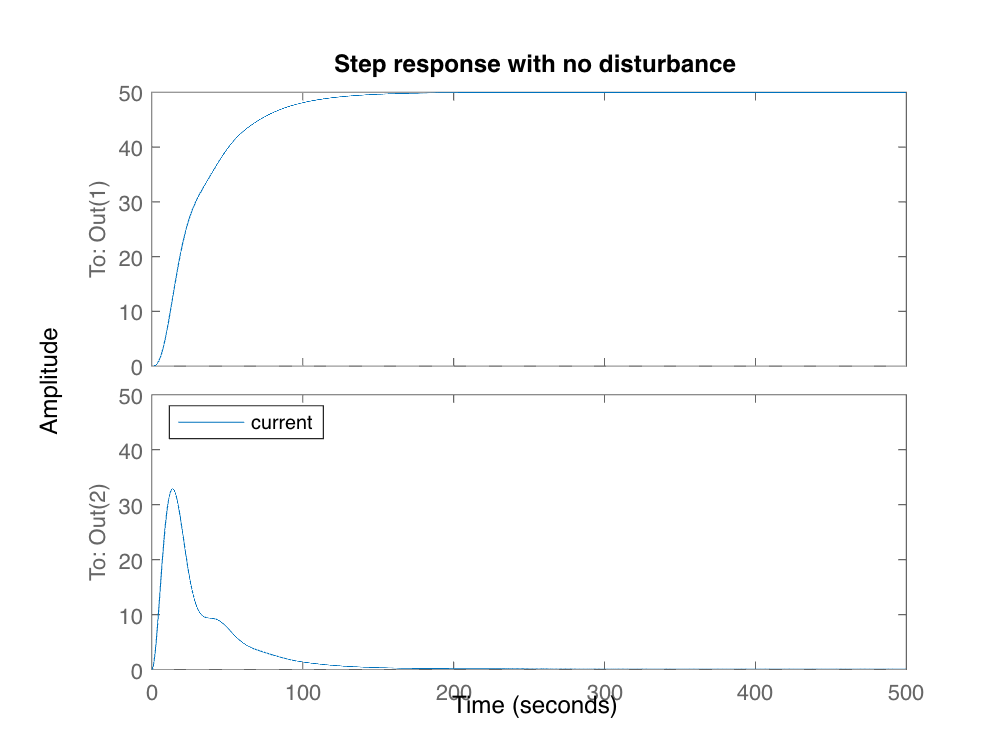

%

u = [50*ones(1,length(Td));zeros(1,length(Td))];
K = 0.015; % 0.01
C_contr = tf(K,[1 0]);            % compensator K/s

cl = feedback(sys_healthy * append(C_contr,1),1,1,1);
h = lsimplot(cl,u,t);
cl_rloc.InputName = {'w_ref','Td'};
cl_rloc.OutputName = 'w';
title('Step response with no disturbance')
legend('current','feedback w/ rlocus','Location','NorthWest')

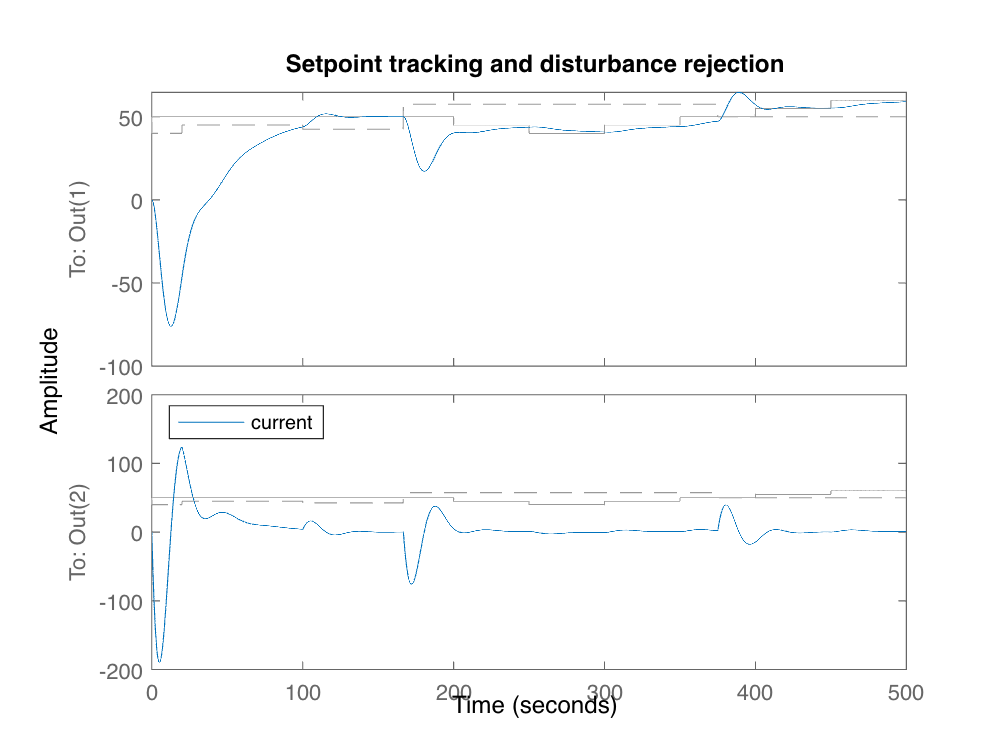


u = [w_ref ; Td];       % w_ref=1 and Td
C_contr = tf(K,[1 0]);            % compensator K/s

cl = feedback(sys_healthy * append(C_contr,1),1,1,1);
h = lsimplot(cl,u,t);
cl_rloc.InputName = {'w_ref','Td'};
cl_rloc.OutputName = 'w';
title('Setpoint tracking and disturbance rejection')
legend('current','feedback w/ rlocus','Location','NorthWest')

## Problem 2:

% Find discrete-time model
% Find Kalman filter
% Ts = 20s
% Evaluate predicted and filtered values
Ts = 20;
q_s = 0.001:0.0005:0.1;
P_s = zeros(length(q_s),1);
Z_s = zeros(length(q_s),1);
for i = 1:length(q_s)
    Qn = q_s(i)*eye(size(A,1));
    Rn = Rc*eye(size(C,1));
    [kest,L,P,M,Z] = kalmd(sys,Qn,Rn,Ts);
    P_s(i) = det(P); % prediction co-variance p(t|t-1)
    Z_s(i) = det(Z); % filtering co-variance P(t|t)
end
figure(4);
plot(q_s,P_s);
hold on;
plot(q_s,Z_s);
ylabel("Value of determinant");
xlabel("Size of Qn");
title("Comparison of steady state performances for different q parameters");
legend("P(t|t-1)","P(t|t)");
legend show

P_min = 1000000;
for i = 1:length(q_s)
    if (P_s(i)<P_min)
        disp("Found minimum")
        P_min = P_s(i);
        i_min = i;
    end
end
Qn = q_s(i_min)*eye(size(A,1));
Rn = 0.1*eye(size(C,1));
[kest,L,P,M,Z] = kalmd(sys,Qn,Rn,Ts);
P %minimal prediction co-variance p(t|t-1)
Z %minimal filtering co-variance P(t|t)

## Problem 3:

% Find Kalman Filter models
% Use asynchronous sampling with controller computation time
% Tc = 10/1/0.1/s
% Compare properties of noise models
% Evaluate P (predicted value)

Ts = 20;
Tcs = [10 1 0.1];
B = [B G];
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;
    Aasync = expm(A*Ts);
    Basync = inv(A)*(expm(A*Ts)-expm(A*0))*B;
    Casync = C*expm(A*etta*Ts);
    Dasync = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;
    
    Q = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
    S = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    R = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    disp("Tc")
    disp(Tcs(i))
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R,S);
    P
end

%% Conclusion: the longer the Tc, the worse is prediction covariance

## Problem 4:

% Show impact of neglecting S in case of asynchronous sampling
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;
    Aasync = expm(A*Ts);
    Basync = inv(A)*(expm(A*Ts)-expm(A*0))*B;
    Casync = C*expm(A*etta*Ts);
    Dasync = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;
    
    Q = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
    S = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    R = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    disp("Tc")
    disp(Tcs(i))
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R,S);
    disp("With S")
    P
    disp("Value of determinant with S")
    disp(det(P))
    disp("With S=0")
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R);
    P
    disp("Value of determinant without S")
    det(P)
end
%% Conclusion: inclusion of S improves prediction covariance for 10 times for Tc = 0.1

## Problem 5:

% Evaluate filtered P(t|t) 
% Use filter design for system with not correlated noise (S=0)
Tc = Tcs(3);
etta = (Ts-Tc)/Ts;

Q = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
S = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
R = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';

A_decor = A - S*inv(R)*C;
B_decor = B - S*inv(R)*D;
Q_decor = Q - S*inv(R)*S';

R = R;

disp("State covariance matrix P(t|t) for system model with decorrelated noise")

[kest,L,P,M,Z] = kalman(ss(A_decor,B_decor,C,D,Ts),Q_decor,R);
Tc
Z
det(Z)
% Conclusion:
% The best values of filtering co-variance P(t|t) is achieved with 
% small Tc = 0.1s

## Additional confirmation of working

[A,B,C,D] = tf2ss(1,[tau^2 2*tau 1]);
G = [1;0];
sys = ss(A,[B G],C,[D 0]);
step_input = ones(1,N+1);
disturbance = [0,W];

noisevec = sqrt(Rc)*randn(N+1,1);
response = lsim(sys,[step_input;disturbance],[0:dt:T]);
y = response+noisevec;

[kest,L,P,M,Z] = kalman(sys,Qc,Rc);
filtered = lsim(kest,[step_input;y'],[0:dt:T]);
figure(5);
plot([0:dt:T],y,'b');
hold on
plot([0:dt:T],filtered(:,1),'r');
title("Noisy and filtered output");
legend("Noisy","Filtered");
hold off

figure(6);

plot([0:dt:T],filtered(:,2),'b');
title("State x1");

figure(7);
plot([0:dt:T],filtered(:,3),'b');
title("State x2");


## Confirmation of asynchronous sampling wokring

G = [1;0];
B = [B G];
Tc = Tcs(3);
etta = (Ts-Tc)/Ts;
Aasync = expm(A*Ts);
Basync = inv(A)*(expm(A*Ts)-expm(A*0))*B;
Casync = C*expm(A*etta*Ts);
Dasync = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;
N= T/Ts;
step_input = ones(1,N+1);

% Wiener Process 
N = T/Ts;
dt = Ts;
dW = zeros(1,N);                % preallocate arrays ...
W = zeros(1,N);                 % for efficiency
dW(1) = Qc*sqrt(dt)*randn();    % first approximation outside the loop ...
W(1) = dW(1);                   % since W(0) = 0 is not allowed
for j = 2:N
    dW(j)= Qc*sqrt(dt)*randn(); % general increment
    W(j) = W(j-1) + dW(j);
end
disturbance = [0,W];
sysAsync = ss(Aasync,Basync,Casync,Dasync,Ts);
noisevec = sqrt(Rc)*randn(N+1,1);
response = lsim(sysAsync,[step_input;disturbance],[0:Ts:T]);
y = response+noisevec;
 
Qasync = Qc;
Sasync = Qc;
Rasync = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';

[kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Qasync,Rasync,Sasync);
P
filtered = lsim(kest,[step_input;y'],[0:Ts:T]);
figure(8);
plot([0:dt:T],y,'b');
hold on
plot([0:dt:T],filtered(:,1),'r');
title("Asynchronous sampling: noisy and filtered output");
legend("Noisy","Filtered");
hold off

figure(9);
plot([0:dt:T],filtered(:,2),'b');
title("State x1");

figure(10);
plot([0:dt:T],filtered(:,3),'b');
title("State x2");

## Additional tools

% Storing figures
if storeFigures
    for i=1:10
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end